### Chapter 1: The Clone Wars (or - how the fork do I start?)

First, ya gotta get the code. Note this is something that any new developer to the project will need to do. The fact that you don't yet know what this project does is half the point. Lucky for you, this project uses the tools we have made available for efficient development. 

Did you do the homework? If not then you don't get to eat dessert tonight, but we will still try to make it meaningful. The homework involved concrete steps for your preparation, as a reminder this includes:

- Installing the R2024a prerelease on your laptop. Note we are not using the -webui option or JSD to start MATLAB. This workshop assumes standard prerelease fucntionality and interfaces.

- Creating a GitHub account (see guidelines [here](https://mathworks.sharepoint.com/:w:/r/sites/eps/esc/web_community/MLCAdmin/_layouts/15/Doc.aspx?sourcedoc=%7BF646BE40-15A8-43E4-922B-EFFAF81F4E62%7D&file=Guidelines%20for%20using%20GitHub%20as%20a%20MathWorks%20Employee%20-%20FAQ.docx&action=default&mobileredirect=true&DefaultItemOpen=1))

- Setting up git such that you ca easily commit and push to GitHub. On Windows, this likely involves leveraging the git credential manager to login to GitHub and access the repo over http. On Linux or MAc this may mean setting up SSH keys for communicating to GitHub. Please address this before the workshop. You should be able to easily authenticate and push to your GitHub repo easily from MATLAB.

- Ensure you can build C++ mex files. If you have WIndows and do not have a compiler installed, this project installs MinGW for you. Please confirm.

Ok, getting starting navigate to [https://github.com/mathworks/Mass-Spring-Damper](https://github.com/mathworks/Mass-Spring-Damper) and log in to GitHub (you have a GitHub account right?)

Fork it by clicking the Fork button

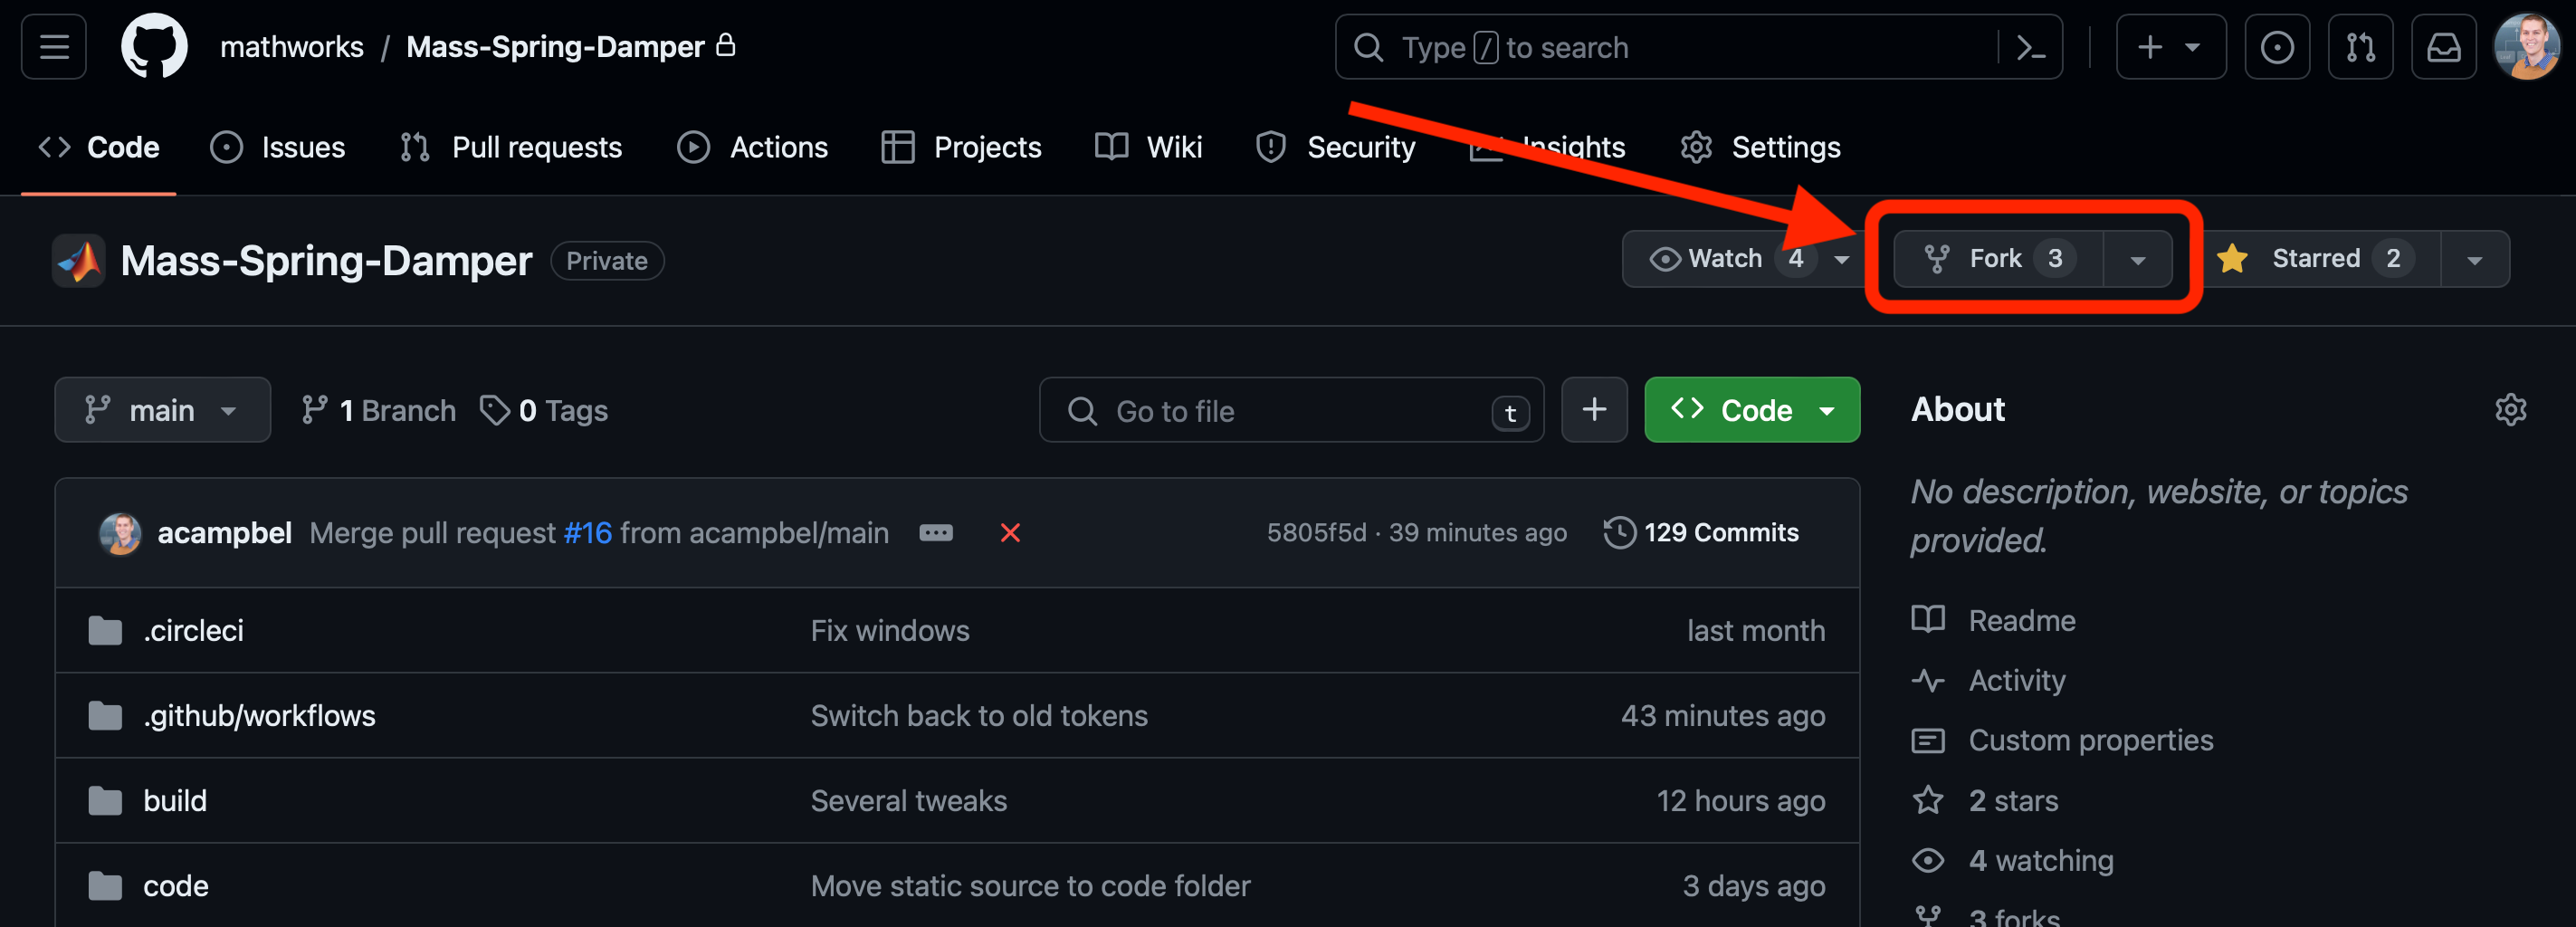

You will need to choose your account and click the button. Super easy.

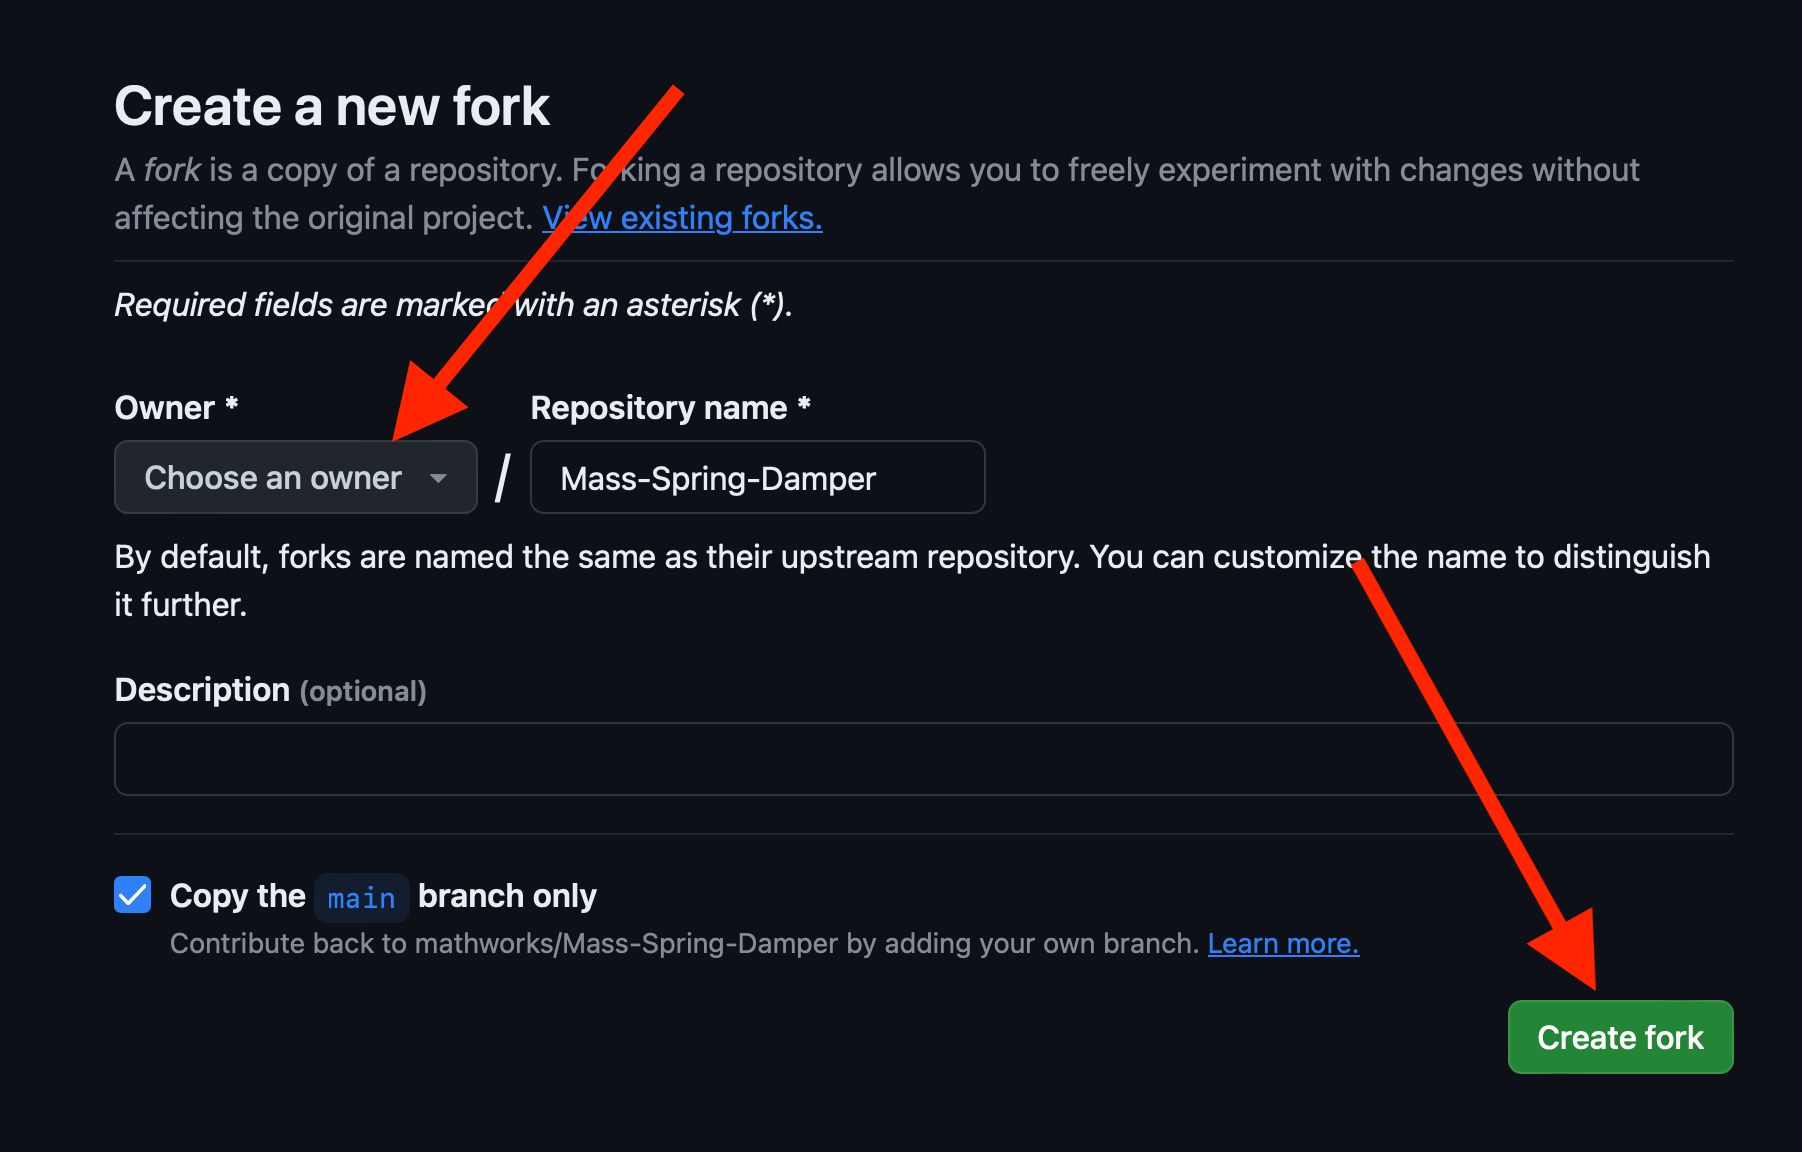

Now you own a repo on your personal org. Congrats! Your mother is very proud.

Before we get into MATLAB, navigate to the Actions tab of your new repository and enable actions.

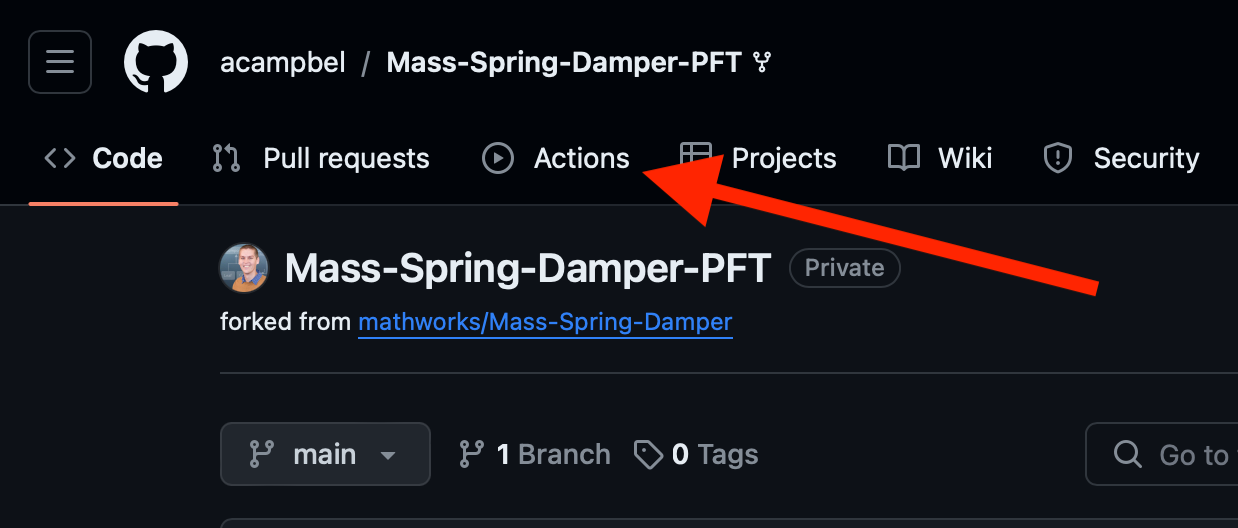

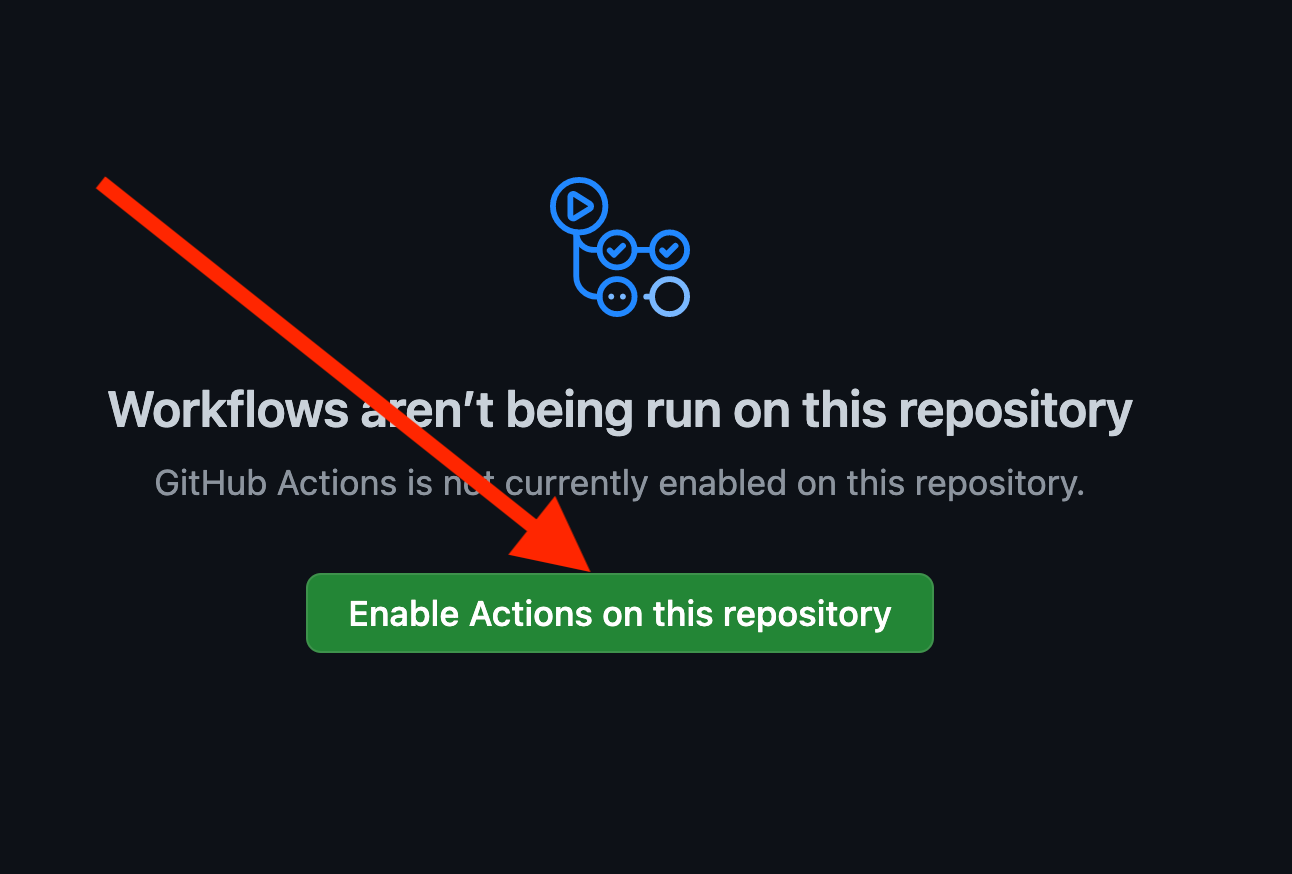

Now click the **MATLAB Build** job on the left, navigate through the **Run workflow** dropdown, and click the green Run workflow button. This will kick off a multi-platform CI build of this repository. It is good to kick it off now so that it can cache our MATLAB installations on the hosted runners and increase performance later on in the workshop.

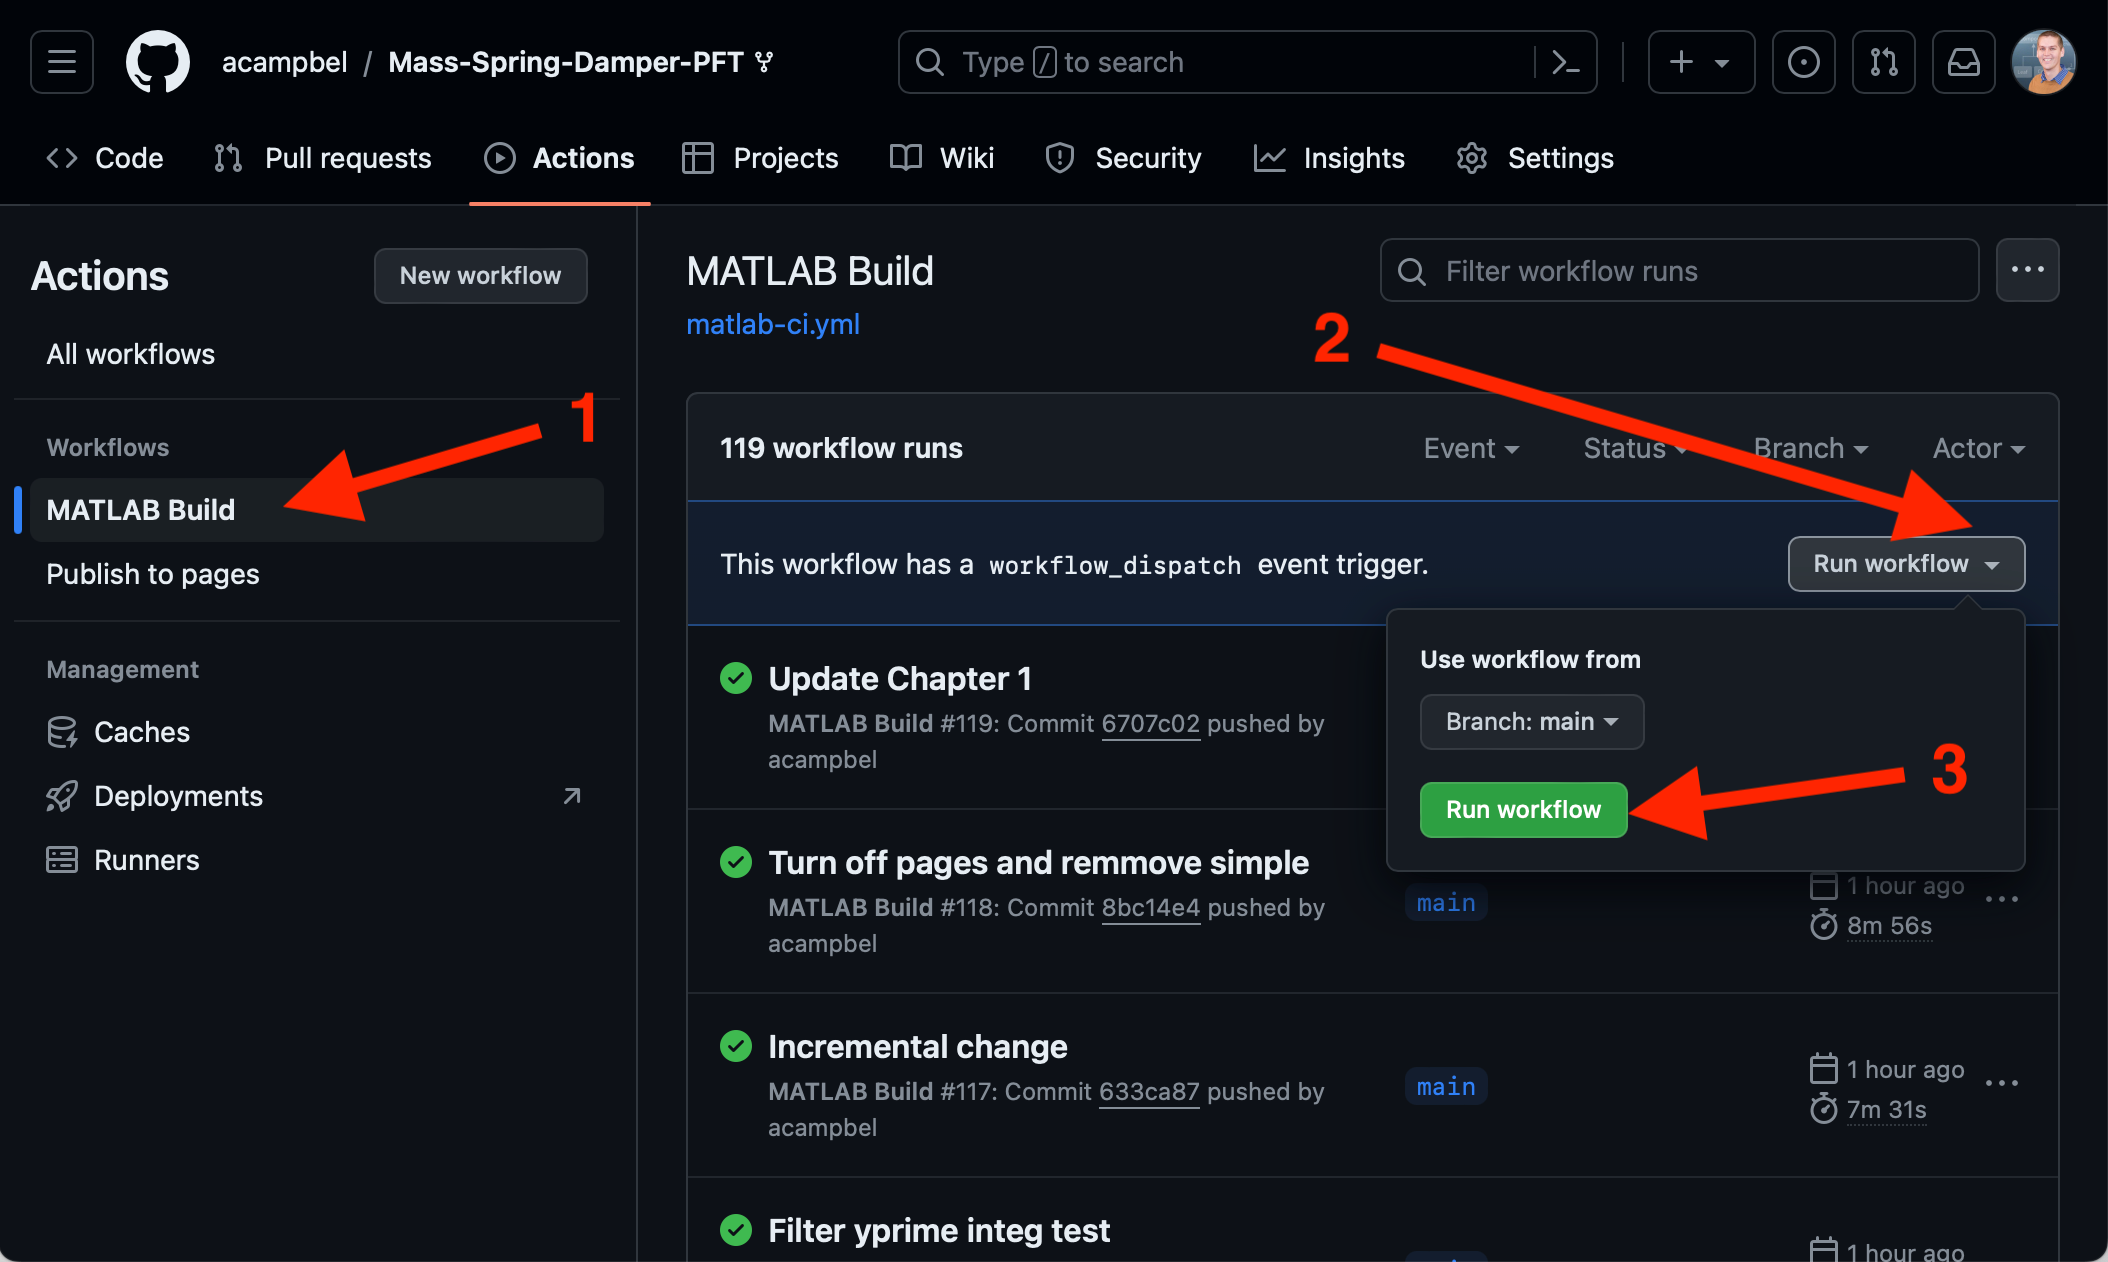

### Bring it to MATLAB

Open up MATLAB on your machine. It needs to be the ***R2024a  Prerelease*** with `MATLAB`, `MATLAB Test`, `MATLAB Compiler`, and `MATLAB Compiler SDK` installed.

Navigate to an empty working folder and clone the code to this folder by naviating to **New** ---> **Project** ---> **From** **Git** 

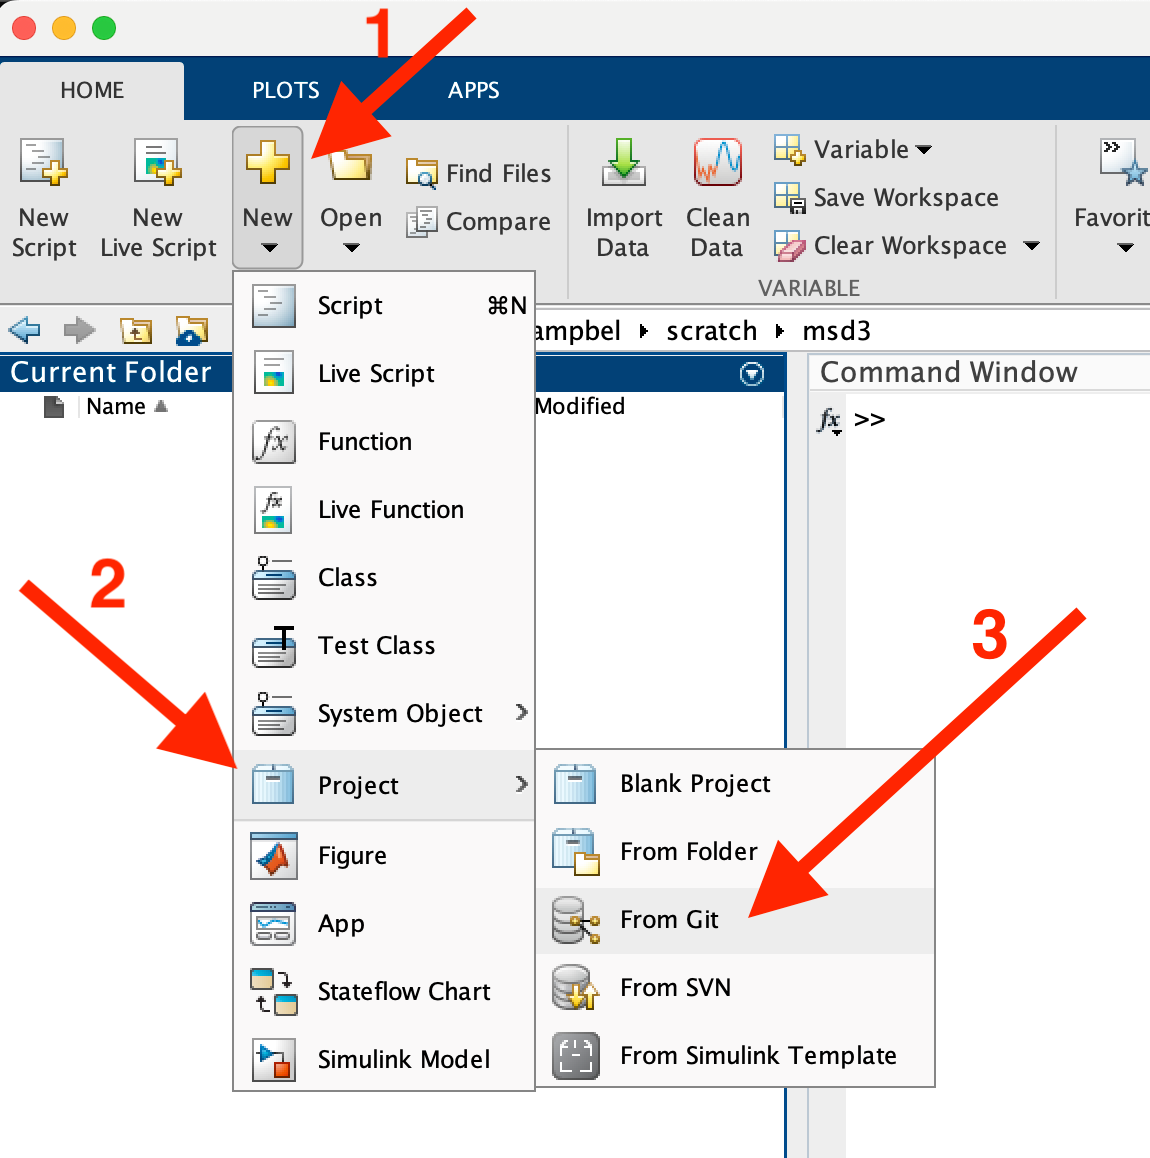

Navigate to your GitHub repo in the browser and copy the location of your repo for cloning. If you are using Windows and already have signed into GitHub on your Windows machine via git credential manager (this was homework) you can just use the **HTTPS** location of the Git repo.  If you are connected to GitHub via ssh keys then copy the **SSH** location.

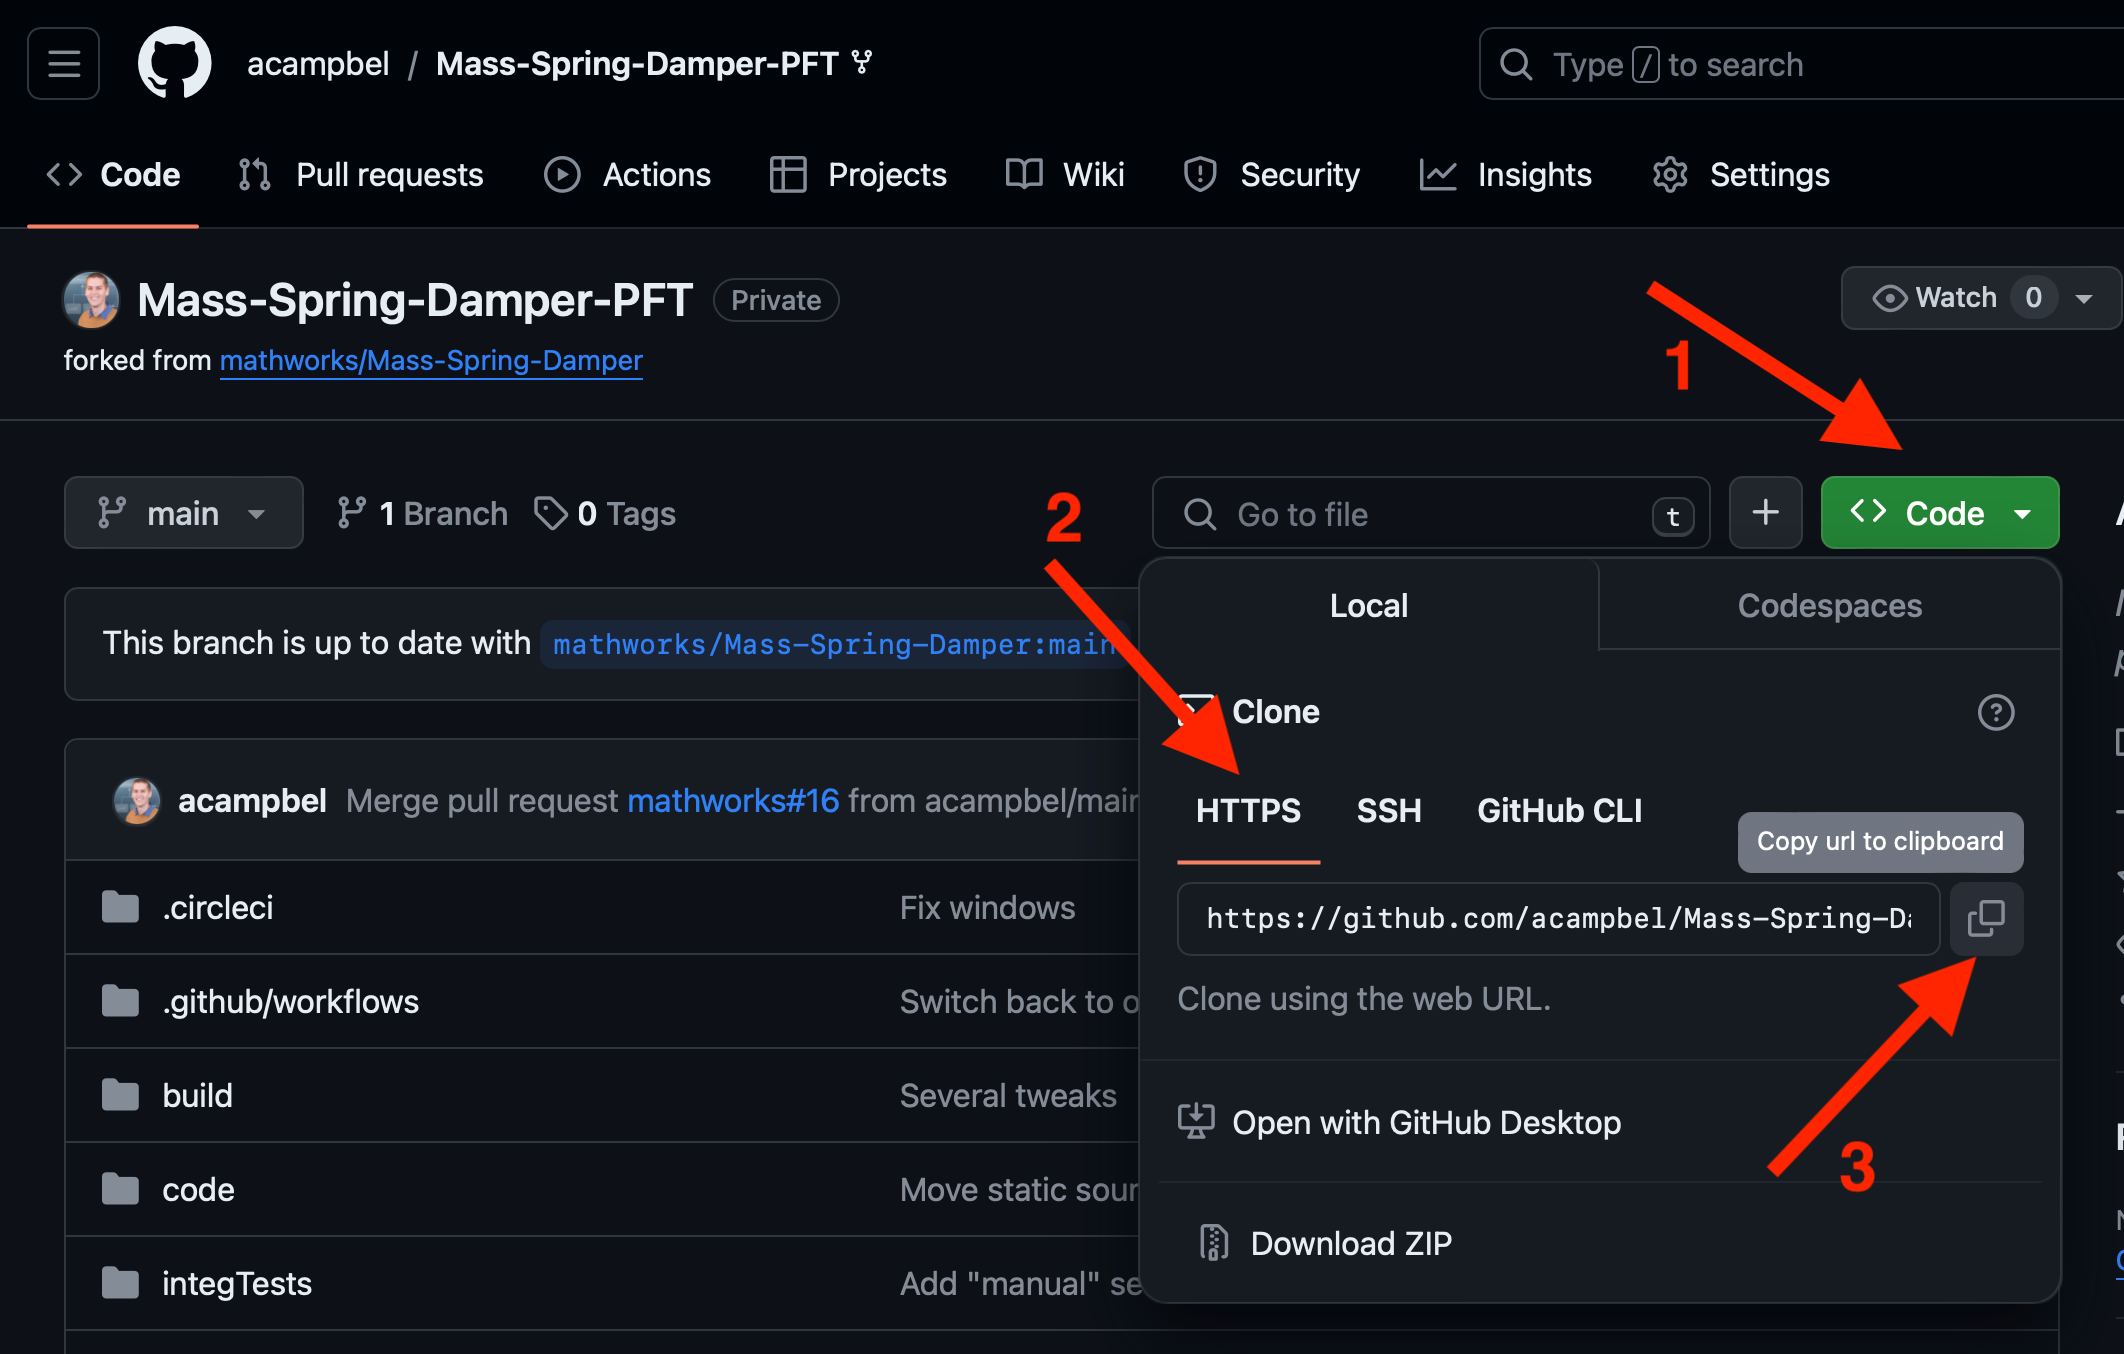

Go back to MATLAB and paste in the location of your repo, navigate to your working folder, and click Retrieve

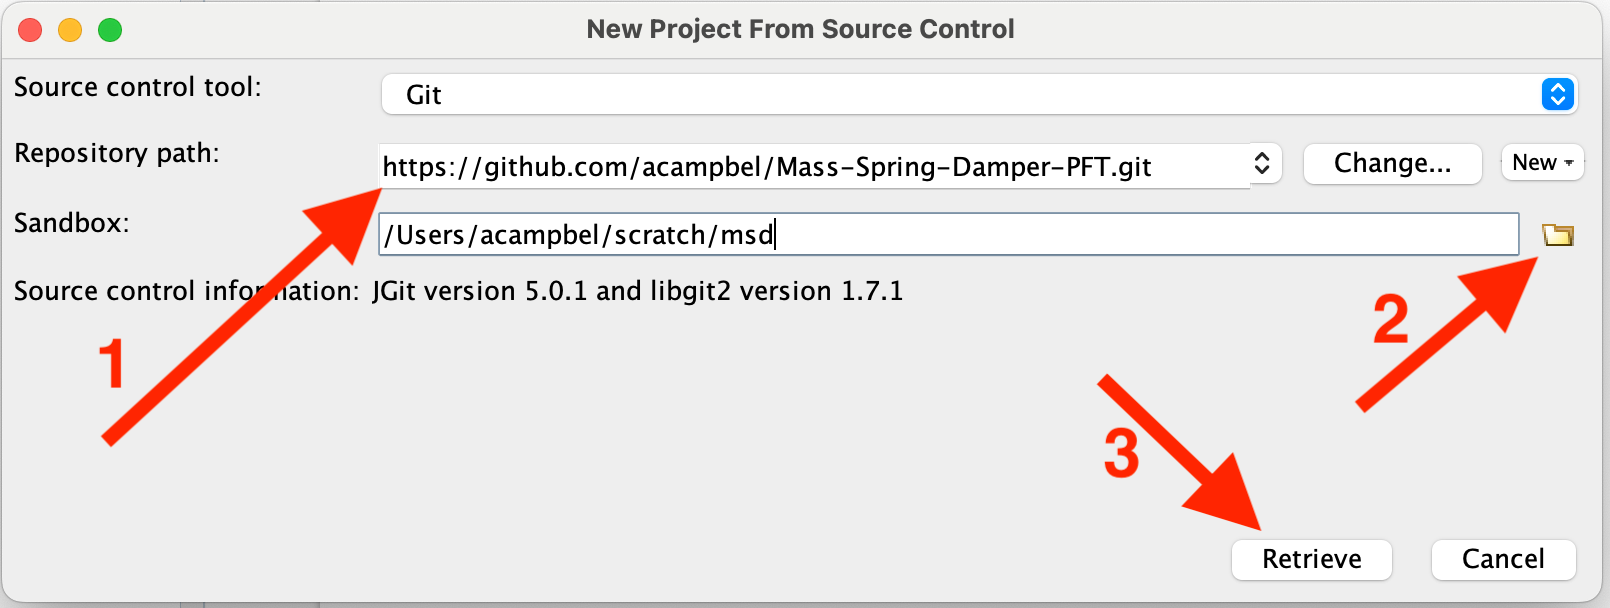

This will create and open the project in the folder you specified.  You now have a fresh clone.

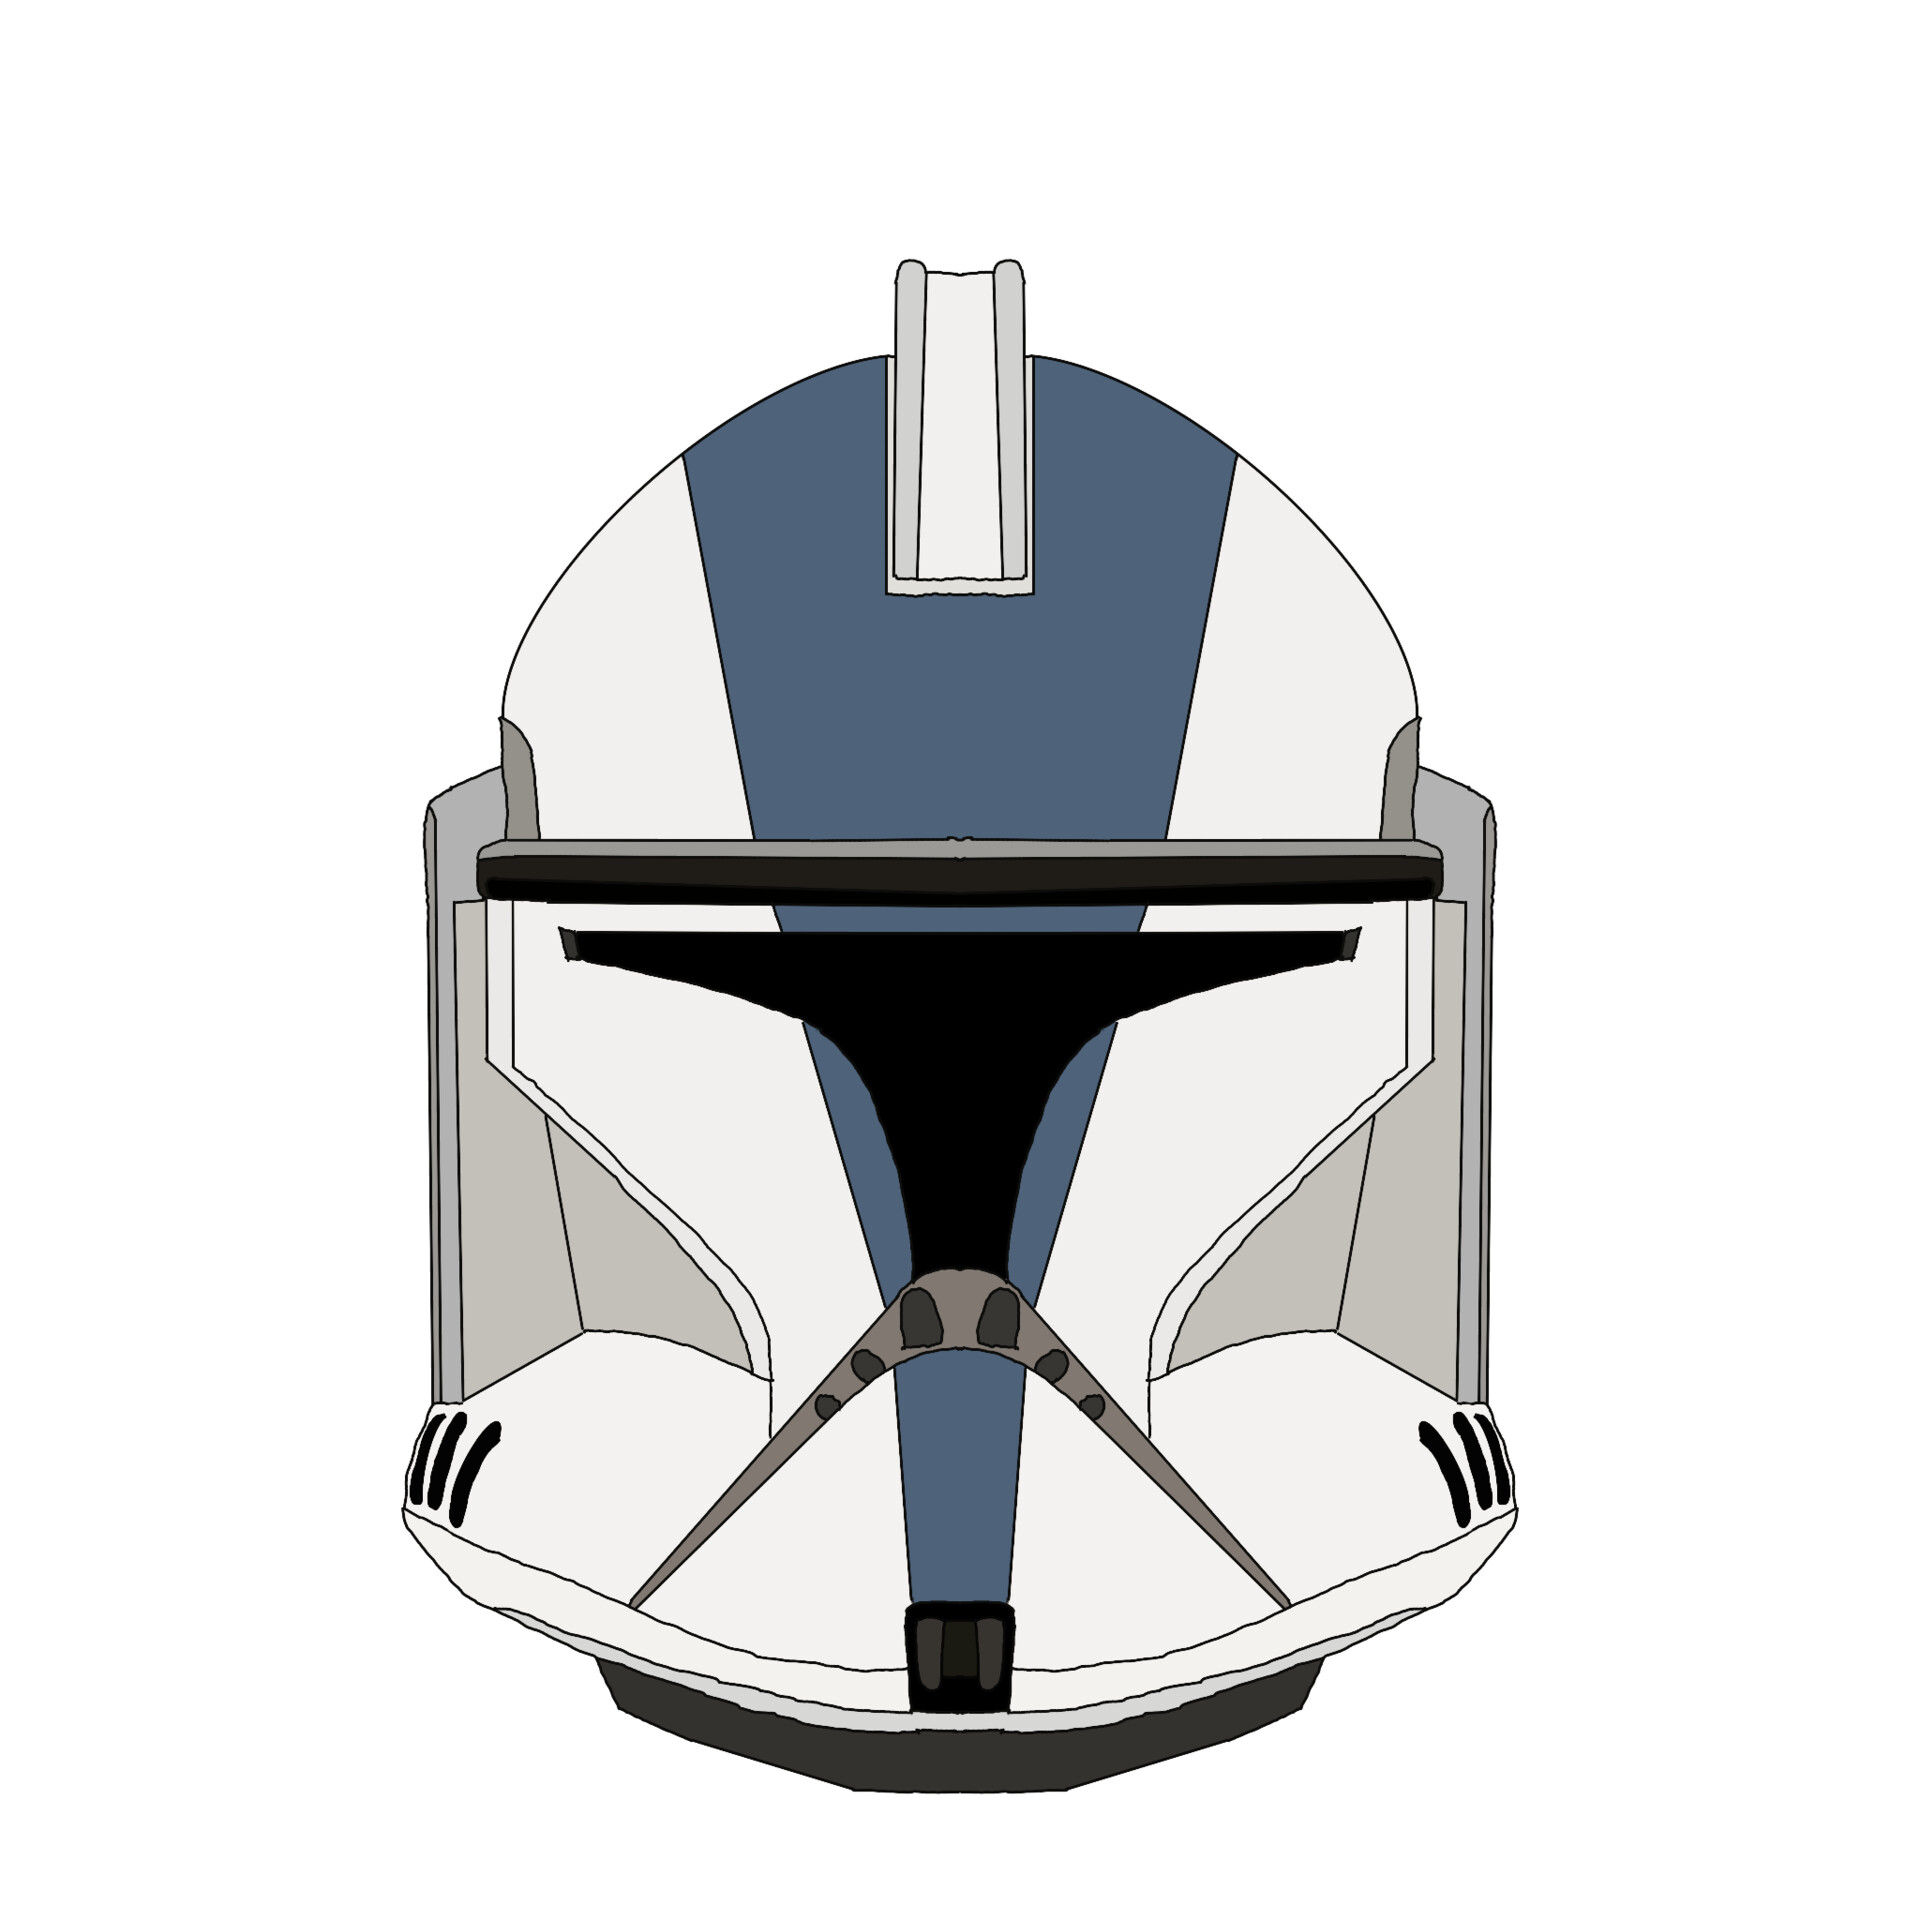

### Push changes

Open the README.md file

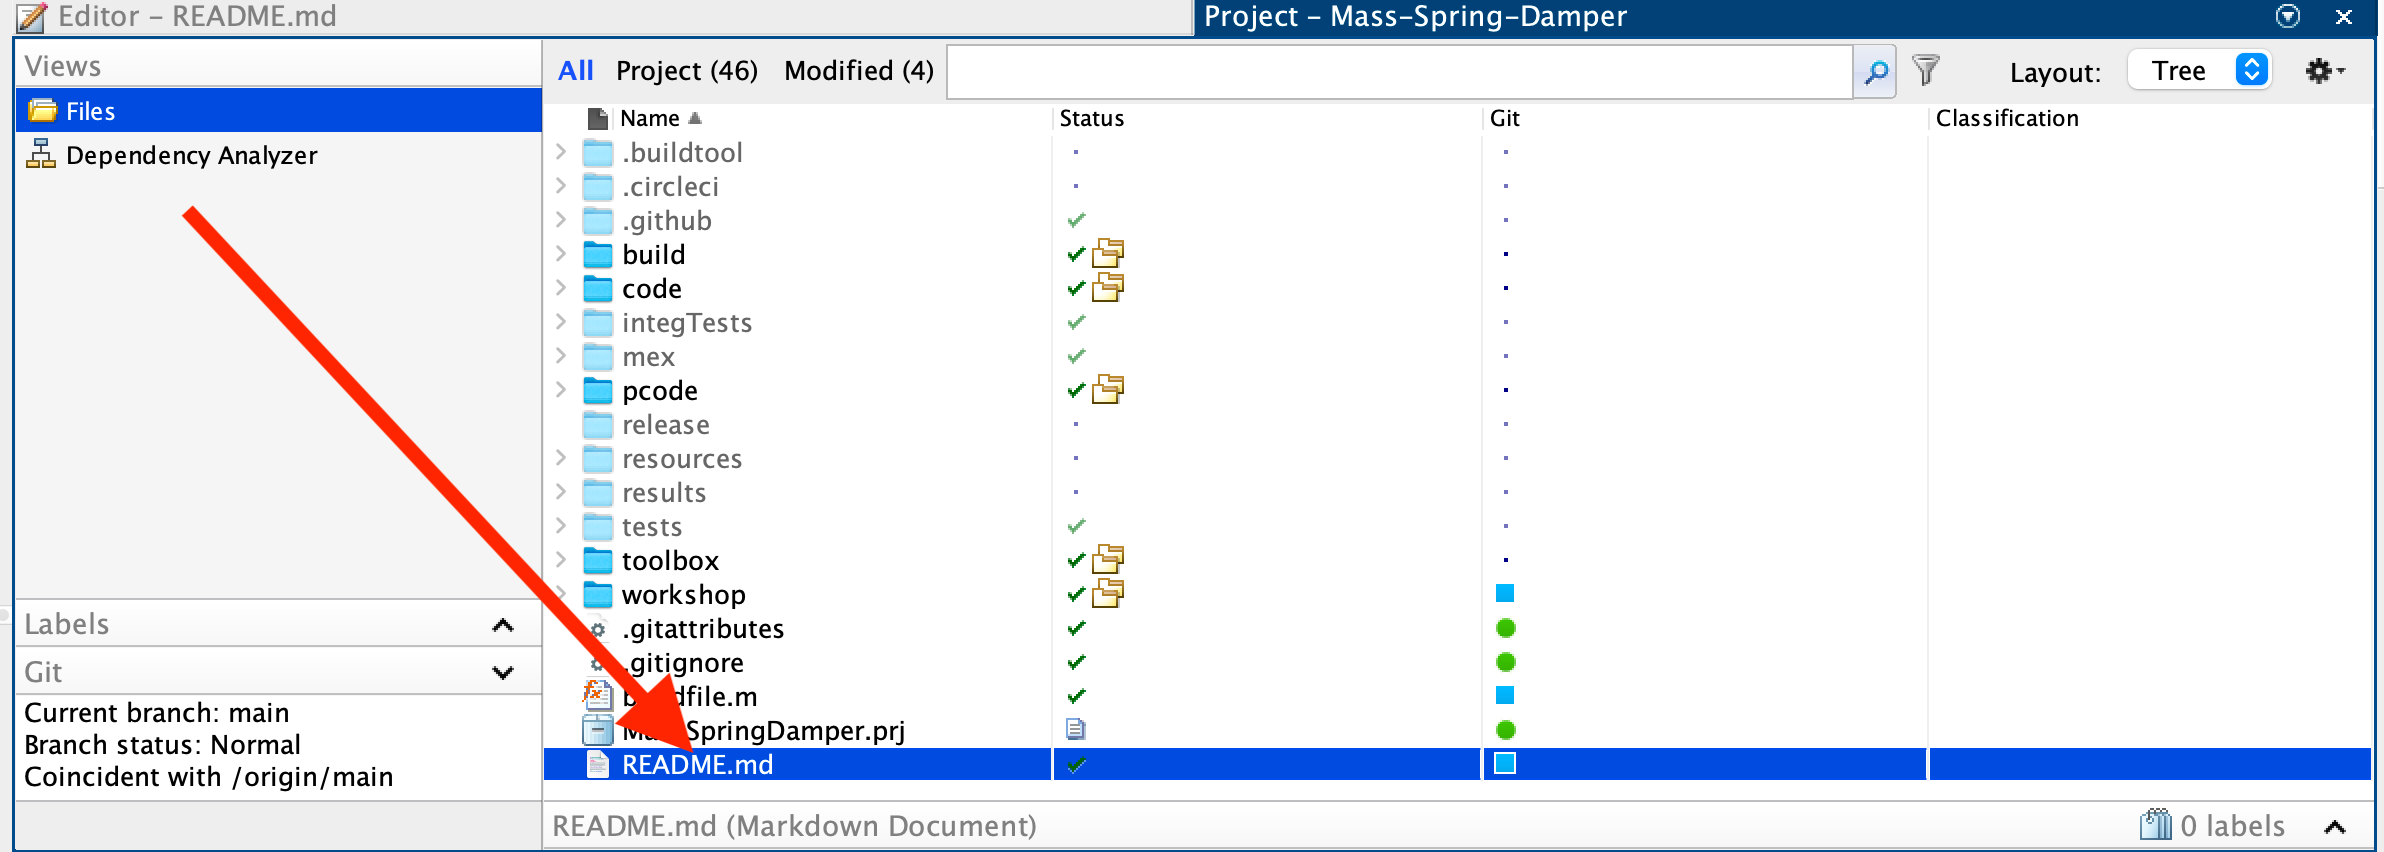

Add your name to the top of the README.md file to denote this is your repo.

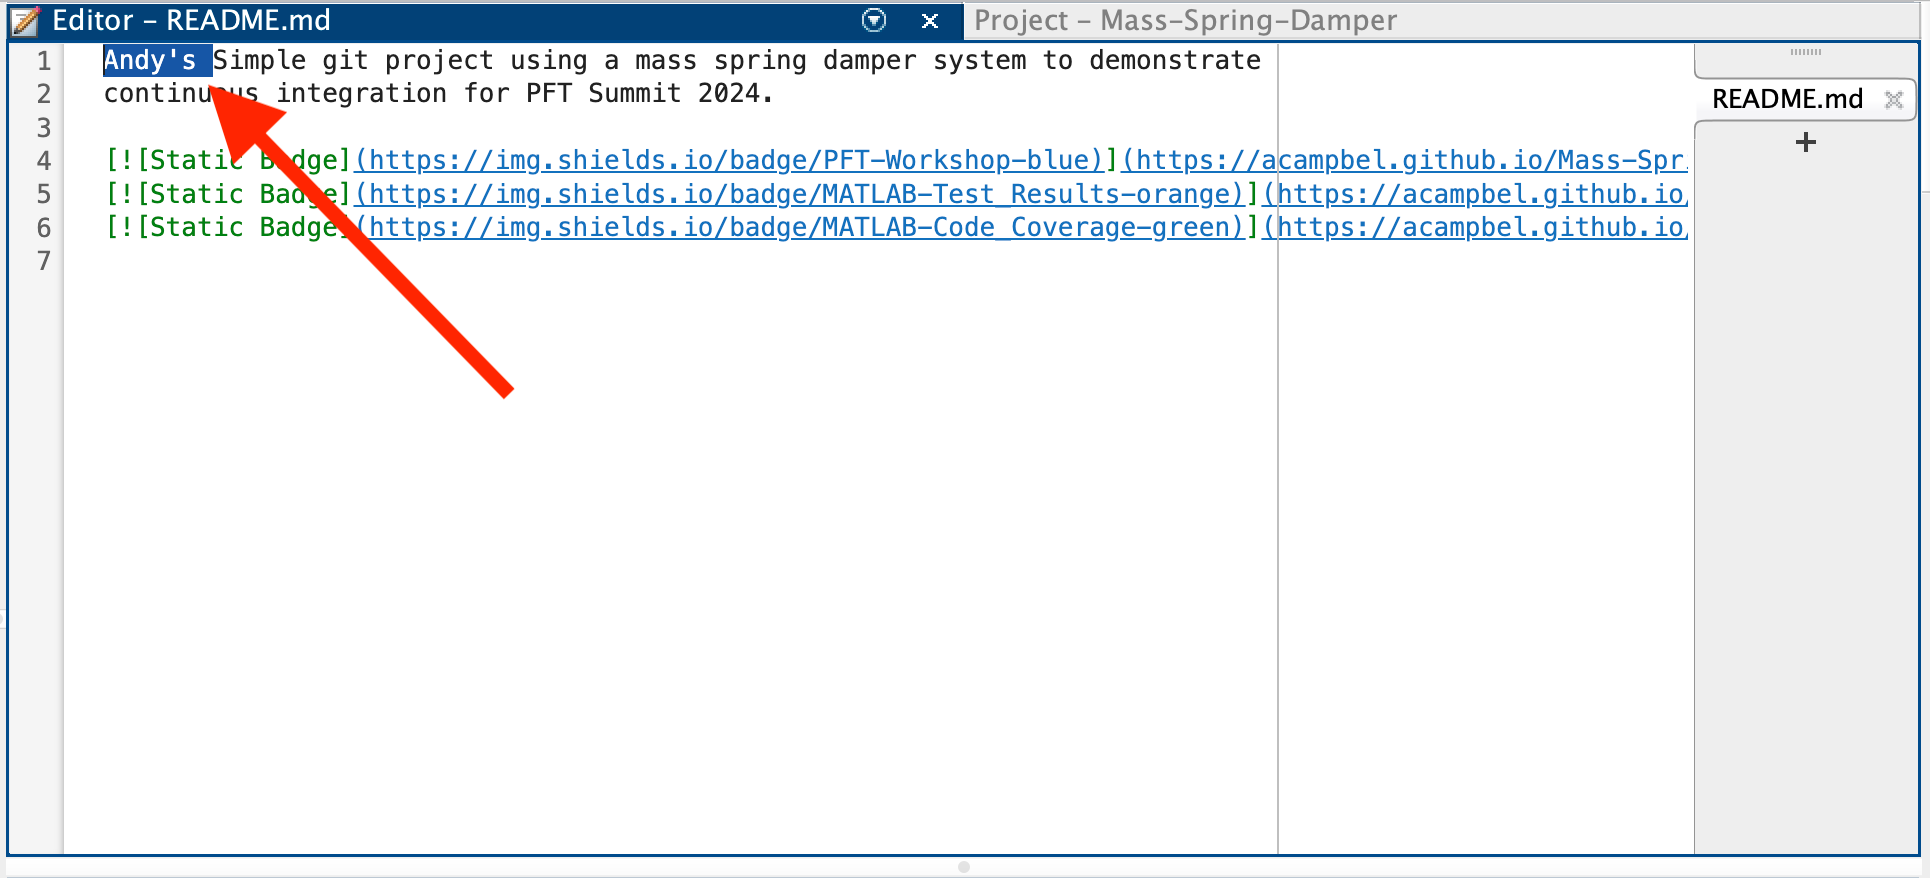

Commit this small change by pressing commit in the project toolstrip

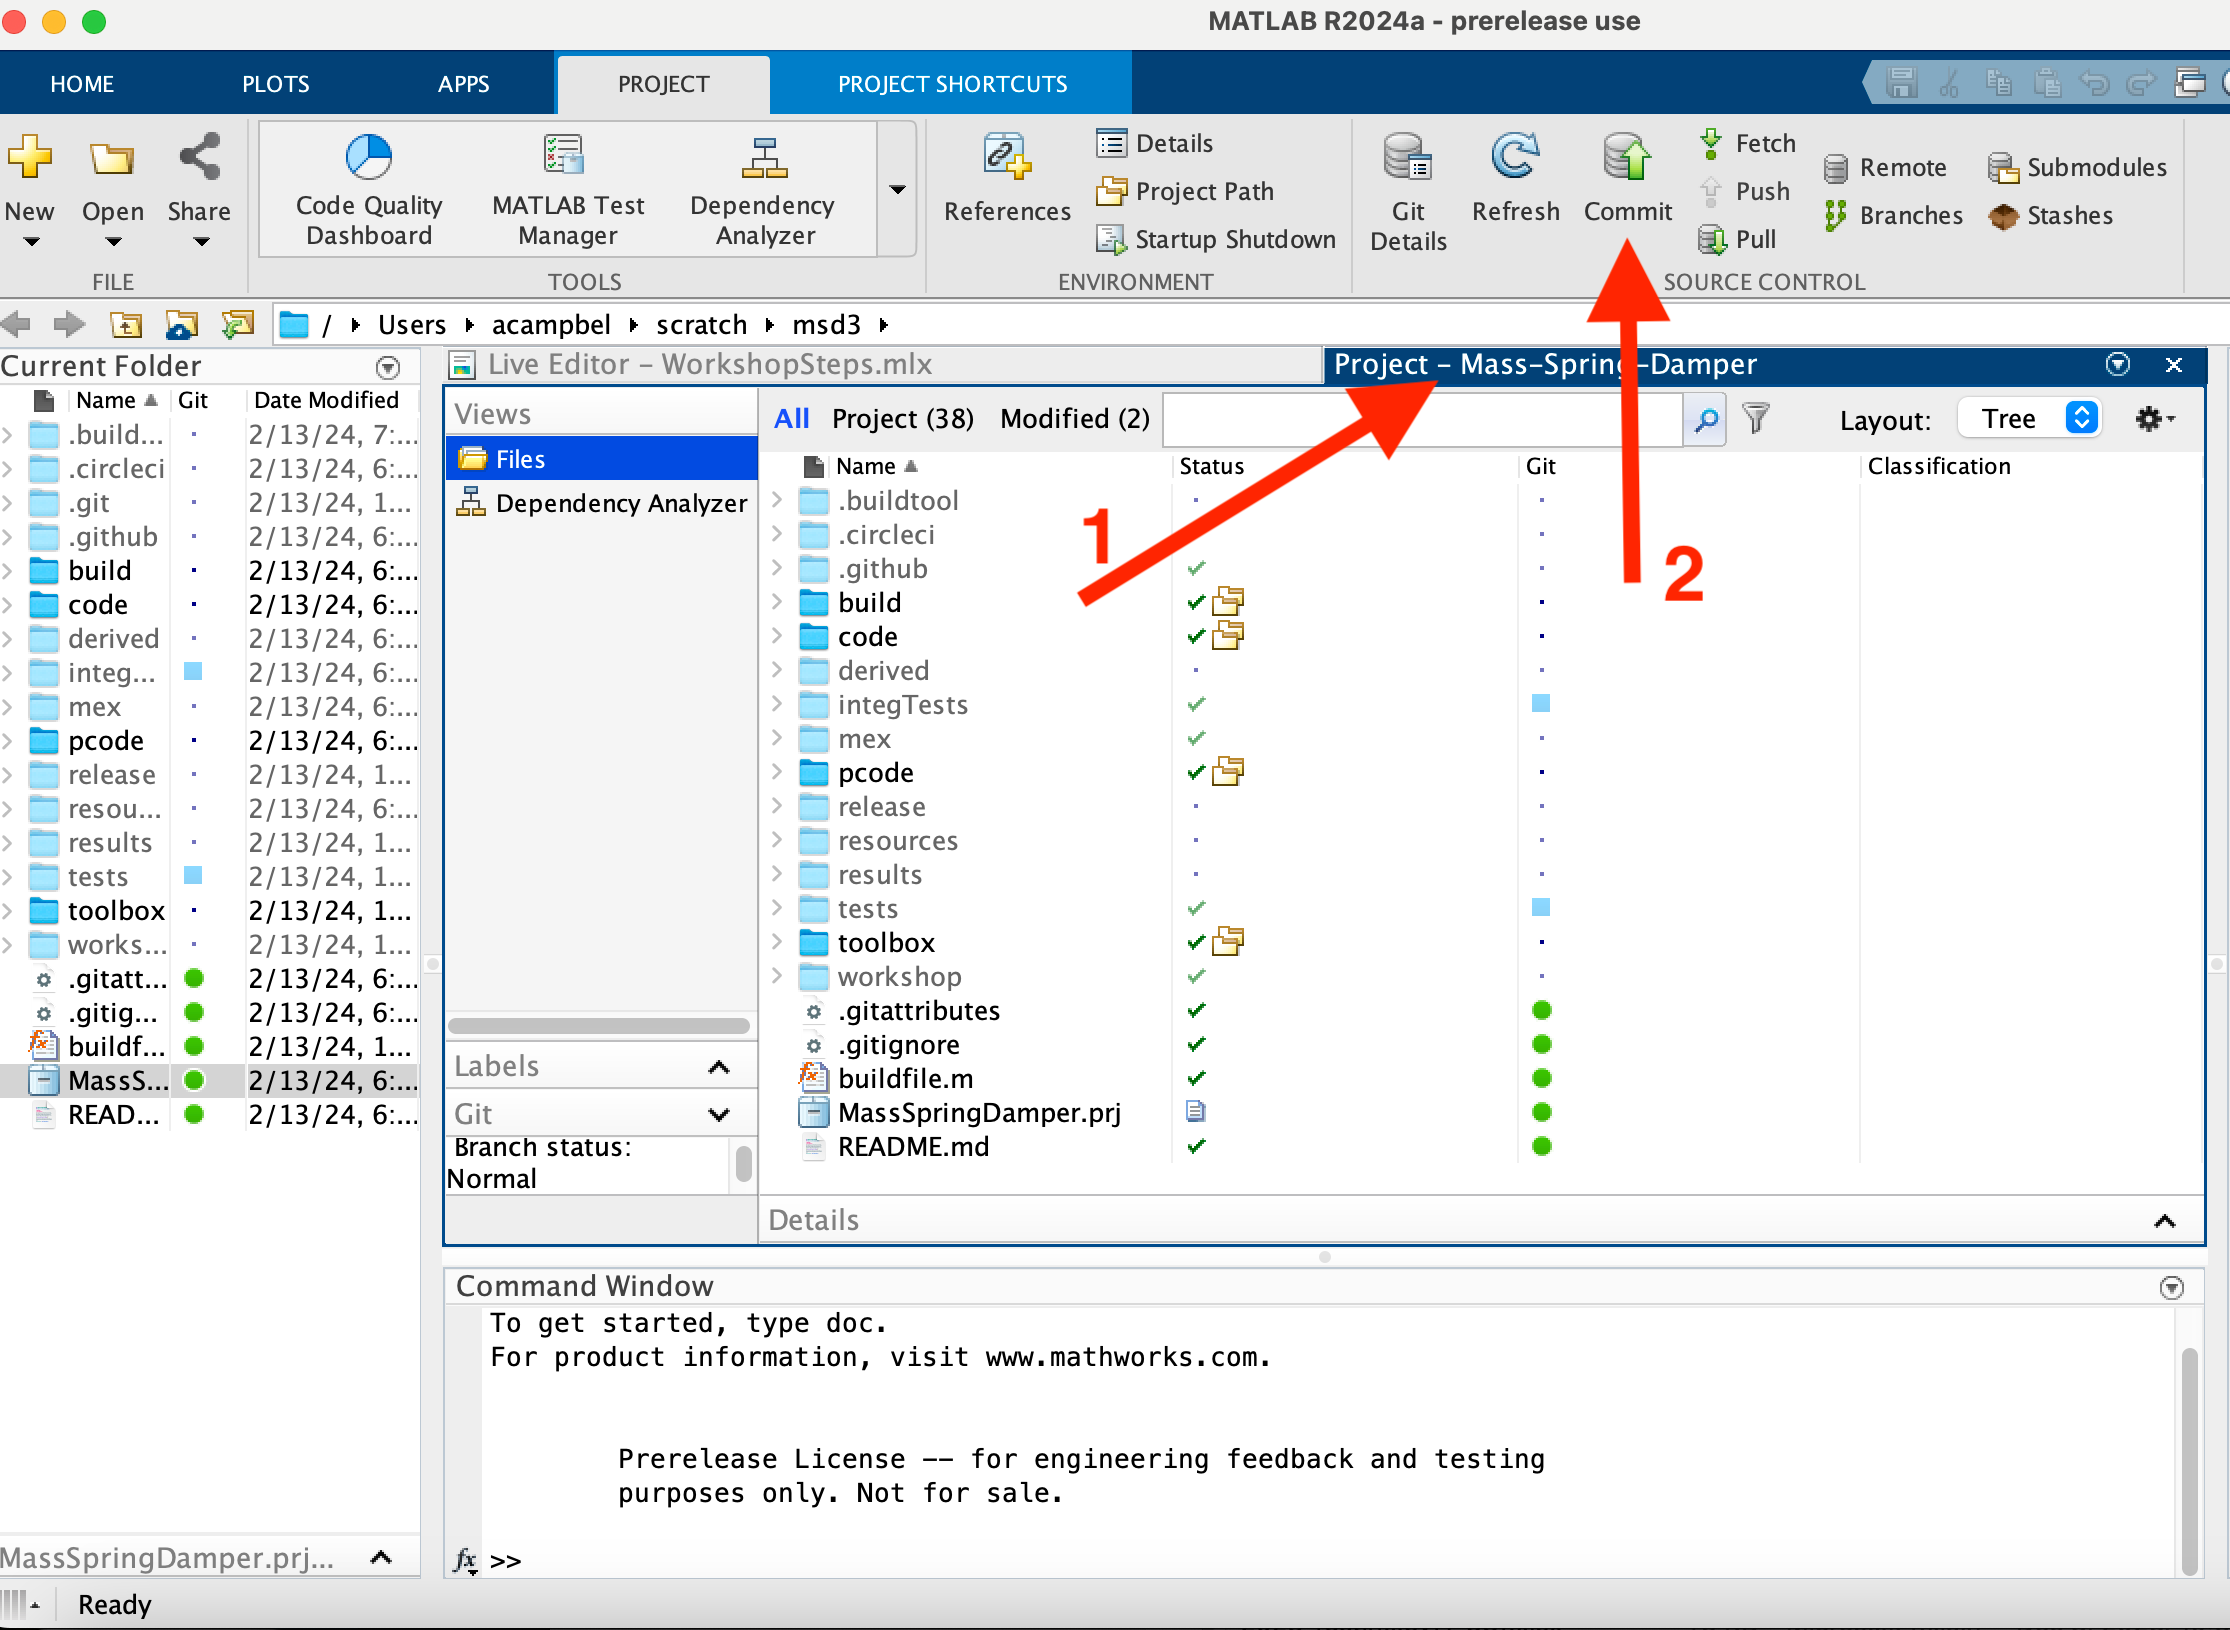

...and in a nice commit message ...

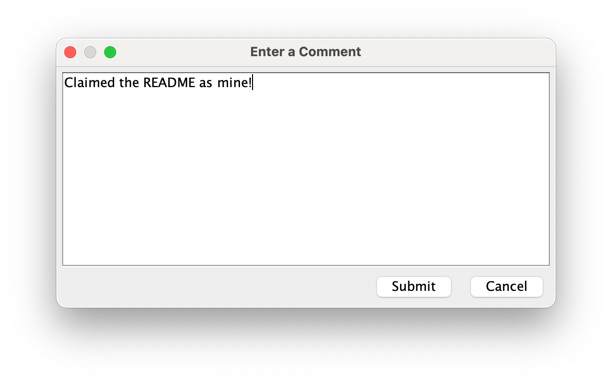

...and then push!

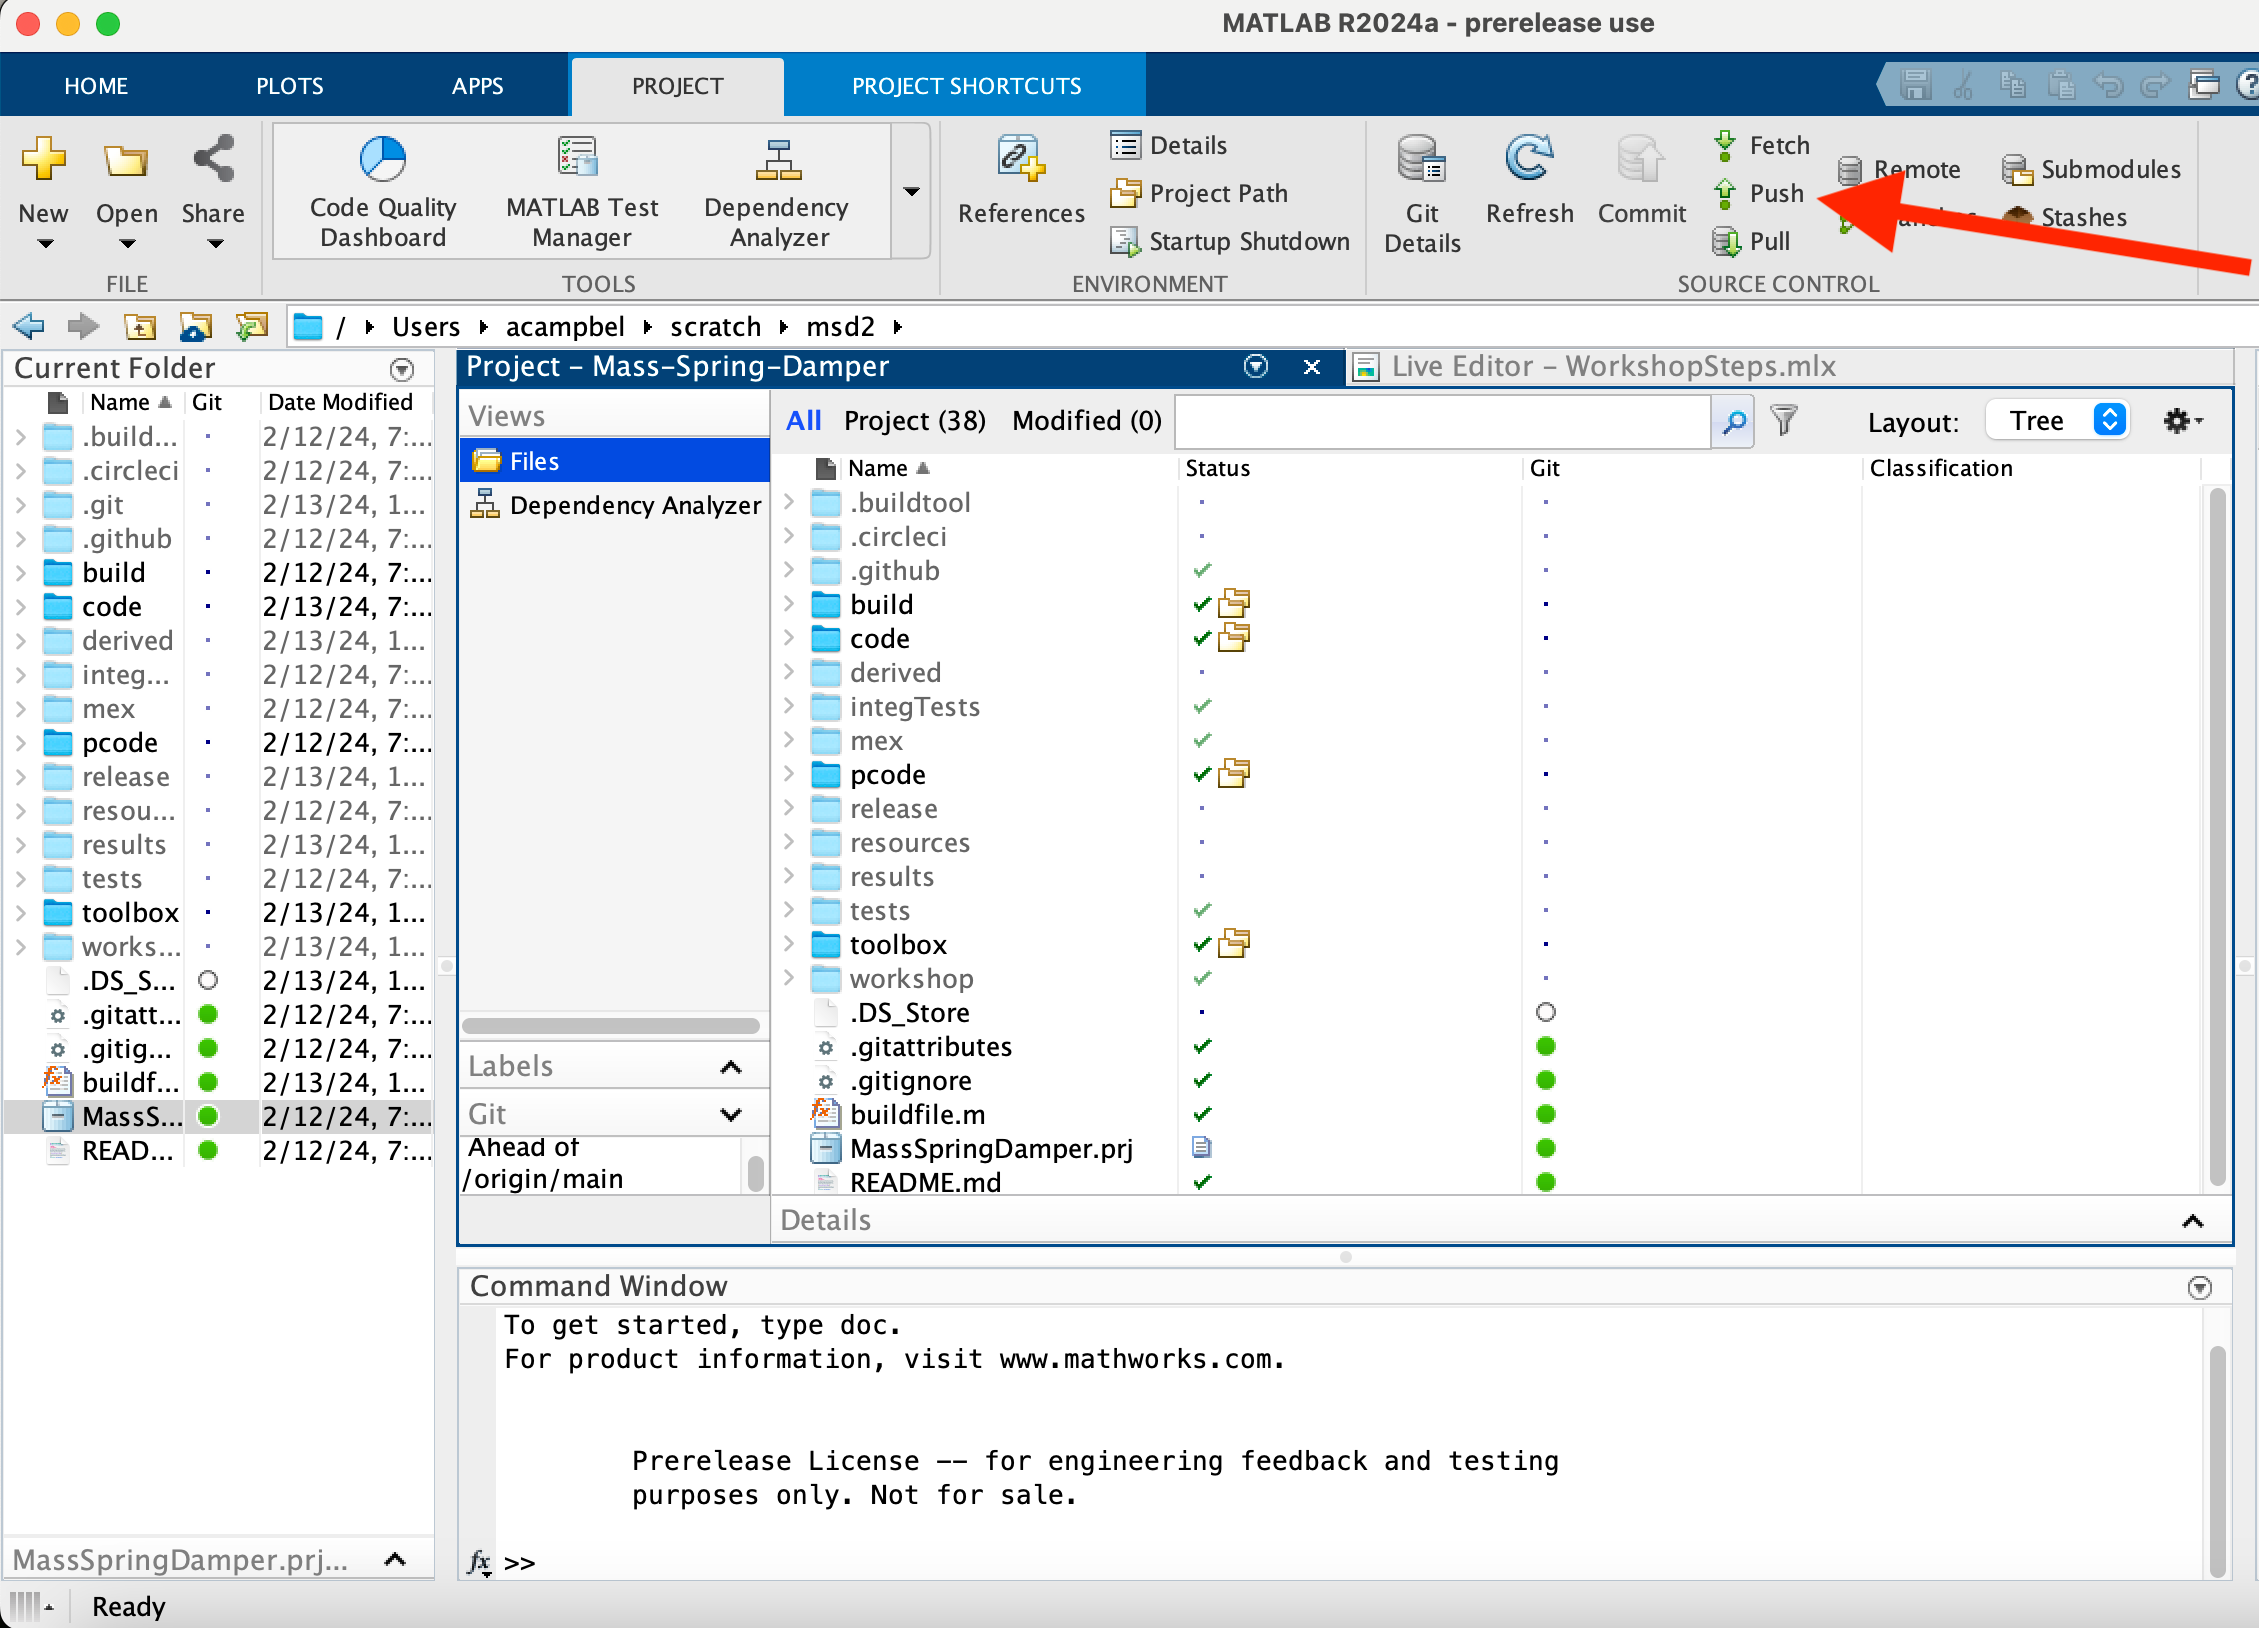

Confirm that you can commit and push to your new GitHub fork. If not, you need to leverage the Git credential manager or set up SSH keys. This is a prerequisite for a productive time at this workshop.

### Check MEX compiler

Last step. Confirm you have a compiler setup correctly. To do this, type

mex -setup

MEX configured to use 'Xcode with Clang' for C language compilation.

To choose a different language, select one from the following:
 mex -setup C++ 
 mex -setup FORTRAN


If this shows that you have a C/C++ compiler configured you are good to go. If it errors due to the lack of a configured compiler and you are on Windows, type the following from the root of this project:

buildtool setupCompiler

** Skipped setupCompiler: up-to-date



This attempts to download and install MinGW for you. If this fails you are on your own to configure the mex compiler. 

Finally, send Winston Yu [an email](mailto:wyu@mathworks.com) to confirm that you have successfully completed Chapter 1 in preparation for the workshop. Congrats, you are ready.

open Chapter_2

#### [Preface & TOC](matlab:open('index.html')) | [Chapter 2](matlab:open('Chapter_2.html'))